# Author: Lucky Yerimah


% Appeneded state DMC and KF for running Nonlinear CSTR plant using a
% linear model.
% Additional function files needed to run simulation:
%       NLmodss to generate linea rmodel
%       NLcstrplant containing nonliner model
%       QSSmpcNLPlant containg the simulation codes which also needs
%           KmatQSS to generate dynamic matrix
%           qSSmpccalc to perform control calculations
%       

ysp = [0];      % setpoint change (from 0 vector); dimension ny
  timesp = 600;   % time of setpoint change
  dist = [0.02];   % magnitude of input disturbance; dimension nd
  delt = 100;              % sample time
  tfinal = 15000;
  timedis = 600;  % time of input disturbance
  
  % first set of parameters to run the Linear model (linearmodSS)
parameters1 = [102 350 -69.71*10^6 8.01 20.75*10^6 69.71*10^6 8314 801 3137 ...
    851 101 10.1 294 1000 4183 294 339.7022 323.7669 0.0842 0.04377 0.011];

  [am,bm, cm, dm] = NLmodss(parameters1);
  
  ninputs = size(bm,2);     % includes disturbance input
  noutputs = size(cm,1);
  nstates = size(am,1);     % number of model states
  sysc_mod = ss(am,bm,cm,dm);
  sysd_mod = c2d(sysc_mod,delt);
  [phi_mod,gamma_stuff,cd_mod,dd_stuff] = ssdata(sysd_mod);
%
  gamma_mod  = gamma_stuff(:,2);   % first input is manipulated
  gammad_mod = gamma_stuff(:,1);   % second disturbances
  
   planteqns = 'NLcstrplant'

planteqns = 'NLcstrplant'

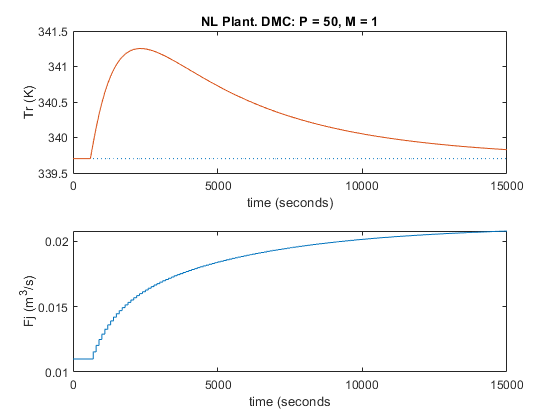

   
   cplant = cm;   % state 2 is the output
  nstates_p = 3;      % three plant states
  
  parvec = [102 350 -69.71*10^6 8.01 20.75*10^6 69.71*10^6 8314 801 3137 ...
    851 101 10.1 294 1000 4183 0.0842 339.7022 323.7669  0.04377 0.011];

p = 50;       % prediction horizon
  m = 1;        % control horizon
  ny = 1;       % number of measured outputs
  nu = 1;       % number of manipulated inputs
  nd = 1;       % number of actual disturbances
  nd_est = 1;   % number of estimated disturbances
  weightu = [0]; % weighting matrix for control action
  weighty = [1];      % weighting matrix for outputs
% constraints
  umin = [-1000];
  umax = [1000];
  dumin = [-1000];
  dumax = [1000];
% Kalman Filter matrices
  Q  = eye(nd_est,nd_est);       % state covariance - need to generalize!
  R  = eye(ny);
%  
Tr_ss = 339.7022; % degree K
Fj_ss = 0.011; % m^3/s

  isim = 1; % additive output disturbance
  iqp = 1;  % unconstrained solution
  noisemag = zeros(ny,1); % no noise
% run simulation
  QSSmpcNLPlant
% zero-order hold on input and setpoint
  [tt,uu] = stairs(t,u');
  [ttr,rr] = stairs(t,r');
%
%  plot the actual plant output without measurement noise
  figure(100);
  subplot(2,1,1)
  plot(ttr,rr+Tr_ss,':',t,y+Tr_ss)
  ylabel('Tr (K)')
  xlabel('time (seconds)')
  title('NL Plant. DMC: P = 50, M = 1')
  subplot(2,1,2)
  plot(tt,uu+Fj_ss)
  ylabel('Fj (m^3/s)')
  xlabel('time (seconds')

  t1 = t; y1 = y+Tr_ss; tt1 = tt; uu1 = uu+Fj_ss; ttr1 = ttr; rr1 = rr+Fj_ss;
  
  

## KF Simulation

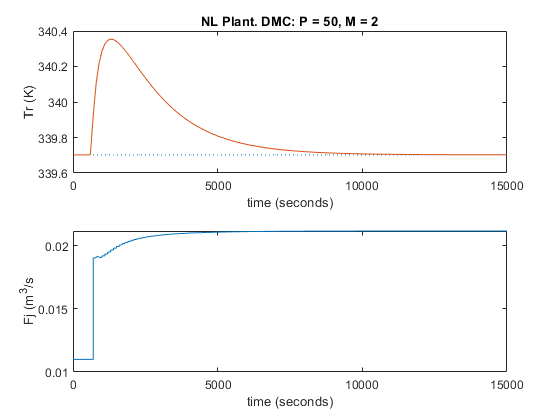

isim = 2; % additive output disturbance
  iqp = 1;  % unconstrained solution
 p = 50;       % prediction horizon
  m = 1;        % control horizon
  QSSmpcNLPlant
% zero-order hold on input and setpoint
  [tt,uu] = stairs(t,u');
  [ttr,rr] = stairs(t,r');
%
%  plot the actual plant output without measurement noise
  figure(200);
  subplot(2,1,1)
  plot(ttr,rr+Tr_ss,':',t,y+Tr_ss)
  ylabel('Tr (K)')
  xlabel('time (seconds)')
  title('NL Plant. DMC: P = 50, M = 2')
  subplot(2,1,2)
  plot(tt,uu+Fj_ss)
  ylabel('Fj (m^3/s')
  xlabel('time (seconds)')

  t2 = t; y2 = y+Tr_ss; tt2 = tt; uu2 = uu+Fj_ss; ttr2 = ttr; rr2 = rr+Tr_ss;
  

## Comparing DMC and KF

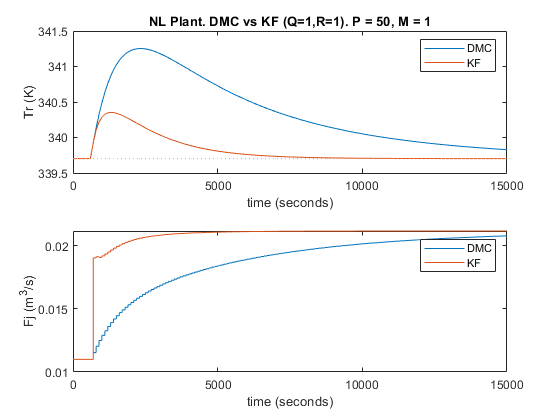

figure(300);
  subplot(2,1,1)
  plot(t1,y1,t2,y2,ttr2,rr2,':')
  legend('DMC','KF')
  ylabel('Tr (K)')
  xlabel('time (seconds)')
  title('NL Plant. DMC vs KF (Q=1,R=1). P = 50, M = 1')
  subplot(2,1,2)
  plot(tt1,uu1,tt2,uu2)
  legend('DMC','KF')
  ylabel('Fj (m^3/s)')
  xlabel('time (seconds)')

## Constrained Simulation DMC

isim = 2; % KF
  iqp = 2;  % constrained solution
 p = 50;       % prediction horizon
  m = 1;        % control horizon
  
  umin = [-0.011];
  umax = [0.1];
  dumin = [-0.01];
  dumax = [0.1];
  
   QSSmpcNLPlant


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

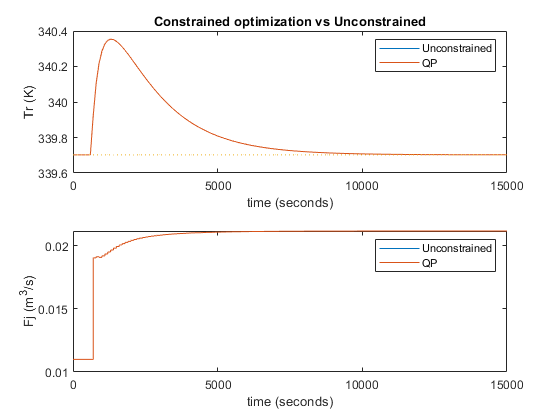

% zero-order hold on input and setpoint
  [tt,uu] = stairs(t,u');
  [ttr,rr] = stairs(t,r');
  t5 = t; y5 = y+Tr_ss; tt5 = tt; uu5 = uu+Fj_ss; ttr5 = ttr; rr5 = rr+Tr_ss;
  
  figure(400);
  subplot(2,1,1)
  plot(t2,y2,t5,y5,ttr5,rr5,':')
  legend('Unconstrained','QP')
ylabel('Tr (K)')
  xlabel('time (seconds)')
  title('Constrained optimization vs Unconstrained')
  
  subplot(2,1,2)
  plot(tt2,uu2,tt5,uu5)
 ylabel('Fj (m^3/s)')
  xlabel('time (seconds)')
  legend('Unconstrained','QP')